% Geostats: 09/16/2021
clear all;
D = load('elevations.txt');

D = D(:); % creates one big long column 
Ix = find(isfinite(D)) %isfinits is putting zeros in a new vector where there are non-finite values 

Ix =      8
     9
    10
    11
    12
    13
    14
    15
    16
    17


                        % and find is finding the values where there are ones and not zeros 

D = D(Ix)

D = 	1.0e+03 *

    2.8803
    2.8788
    2.8774
    2.8759
    2.8738
    2.8657
    2.8576
    2.8496
    2.8436
    2.8402



     % and find is finding the values where there are ones and not zeros

## PROBLEM 1

D_min = min(D); %min, max, std, and mean find the minimum maximum, standard deviation, and mean of what ever data they are given 
D_max = max(D);
D_std = std(D);
D_mean= mean(D);
nbins = 100; % set number of bins 
x0 = (D_mean-100*D_std):D_std/100:(D_mean+100*D_std); %sort the values from least to greatest by 10 off the average

## PROBLEM 2

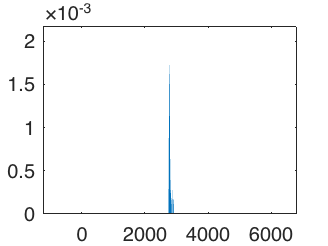

figure(1)
 
[distr, xbins]= hist(D, x0); %creates histogram 
dx = D_std/10; %bin width
distr = distr / sum(distr*dx); %length of bins 
bar(xbins, distr) %plot the relative  density histrogram problem

## PROBLEM 3

RD = randsample(D,10,true) % draws 10 random numbers from D, the true removes the number and stores it and picks remaining values from new list of data

RD = 	1.0e+03 *

    2.7720
    2.7697
    2.7734
    2.7740
    2.9059
    2.7625
    2.8928
    2.8047
    2.8257
    2.8042


RD_mean = mean(RD)

RD_mean = 2.8085e+03

RD_min= min(RD)

RD_min = 2.7625e+03

RD_max= max(RD)

RD_max = 2.9059e+03

## PROBLEM 4

for i=1:1000; %index into list the length of 1000 with 1000 samples 

   RD = randsample(D,10,true);
   RD_mean(i)= mean(RD);
   RD_min(i) = min(RD);
   RD_max(i) = max(RD);
   RD_std(i) = std(RD);
  
end % the for loop stores the values for each index (I) and creates arrays for the min, max, mean, and std 

## PROBLEM 5

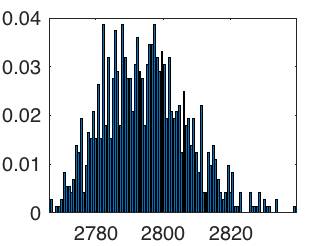

figure(2)
[distr_mean, xbins_mean]= hist(RD_mean, nbins); % these are the sane commands as explained in problem 2 excpet carrie dout for std, mean, min, and max specificaly 
dx_mean = xbins_mean(2)-xbins_mean(1);
distr_mean = distr_mean / (sum(distr_mean.*dx_mean));
bar(xbins_mean, distr_mean) %plot the relative  density histrogram problem

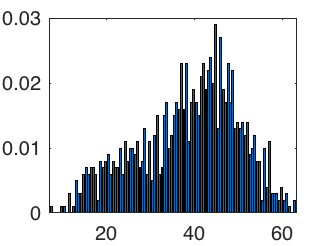


figure(3)
[distr_std, xbins_std]= hist(RD_std, nbins);
dx_std = xbins_std(2)-xbins_std(1);
distr_std = distr_std / sum(distr_std);
bar(xbins_std, distr_std) %plot the relative  density histrogram problem

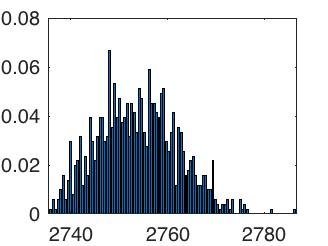


figure(4)
[distr_min, xbins_min]= hist(RD_min, nbins);
dx_min = xbins_min(2)-xbins_min(1);
distr_min = distr_min / sum(distr_min.*dx_min);
bar(xbins_min, distr_min) %plot the relative  density histrogram problem

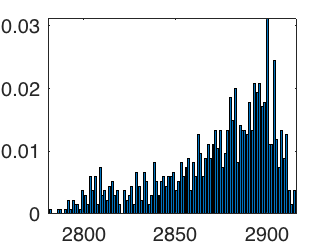



figure(5)
[distr_max, xbins_max]= hist(RD_max, nbins);
dx_max = xbins_max(2)-xbins_max(1);
distr_max = distr_max / sum(distr_max.*dx_max);
bar(xbins_max, distr_max) %plot the relative  density histrogram problem

## PROBLEM 6

ND = load('elevations.txt'); % load elevations.txt data
ND = ND(:); %make it one long column 
zx = std(D)/10; %set bin width 
z0 = (mean(D)-std(D)*10):zx:(mean(D)+std(D)*10) %create bin spacing 

z0 = 	1.0e+03 *

    2.3931    2.3971    2.4011    2.4051    2.4091    2.4131    2.4172    2.4212    2.4252    2.4292    2.4332    2.4372    2.4413    2.4453    2.4493    2.4533    2.4573    2.4614    2.4654    2.4694    2.4734    2.4774    2.4814    2.4855    2.4895    2.4935    2.4975    2.5015    2.5055    2.5096    2.5136    2.5176    2.5216    2.5256    2.5296    2.5337    2.5377    2.5417    2.5457    2.5497    2.5537    2.5578    2.5618    2.5658    2.5698    2.5738    2.5778    2.5819    2.5859    2.5899


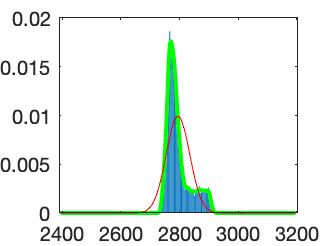

[N, xbins]= hist(D,z0); %standard histogram fucntion like before 
RDH = N/sum(N*zx);
figure(6);
bar(z0,RDH)
h = 10; %window size 
clear f;
for n=1:length(z0)
    dist = (D-z0(n)); %distance from x0 to all other data values
    Idx = find(abs(dist)<h); %finding all data points within h from x0
    w =15/16*(1-(dist(Idx)/h).^2).^2; %weights of all points
    f(n) =sum(w); %sum the weights 

end 

zx = std(D)/10;
f= 1/sum(f*zx)*f;%normalized pdf 
gauss = mypdf(z0,D_mean, D_std);


figure(6); hold on 
 plot(z0, f, 'g', 'linewidth', 2)
plot(z0, gauss, 'r')

## PROBLEM 7

## for ther sample mean

figure(7); hold on
bar(xbins_mean, distr_mean)%For mean distribution values 
mu_0 = std(RD_mean)/10;
RD_0 = (mean(RD_mean)-std(RD_mean)*10):mu_0:(mean(RD_mean)+std(RD_mean)*10)

RD_0 = 	1.0e+03 *

    2.6710    2.6723    2.6735    2.6747    2.6760    2.6772    2.6784    2.6797    2.6809    2.6822    2.6834    2.6846    2.6859    2.6871    2.6883    2.6896    2.6908    2.6921    2.6933    2.6945    2.6958    2.6970    2.6982    2.6995    2.7007    2.7020    2.7032    2.7044    2.7057    2.7069    2.7081    2.7094    2.7106    2.7118    2.7131    2.7143    2.7156    2.7168    2.7180    2.7193    2.7205    2.7217    2.7230    2.7242    2.7255    2.7267    2.7279    2.7292    2.7304    2.7316


RDmu = mean(RD_mean)

RDmu = 2.7948e+03

RDsig = std(RD_mean)

RDsig = 12.3741

mu_g = mypdf(RD_0, RDmu, RDsig) % use mypdf function 

mu_g =     0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


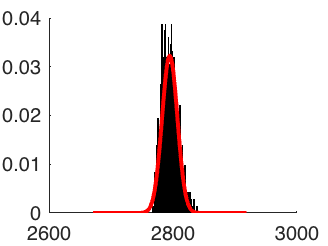


plot(RD_0, mu_g, 'r', 'linewidth', 2) % plot norm distrabution curve 

## for the sample standard deviation

figure(8); hold on
bar(xbins_std, distr_std)
std_0 =std(RD_std)/10;
RDstd_0 = (mean(RD_std)-std(RD_std)*10):std_0:(mean(RD_std)+std(RD_std)*10)

RDstd_0 =   -74.8965  -73.7610  -72.6255  -71.4900  -70.3545  -69.2189  -68.0834  -66.9479  -65.8124  -64.6769  -63.5414  -62.4059  -61.2703  -60.1348  -58.9993  -57.8638  -56.7283  -55.5928  -54.4573  -53.3218  -52.1862  -51.0507  -49.9152  -48.7797  -47.6442  -46.5087  -45.3732  -44.2377  -43.1021  -41.9666  -40.8311  -39.6956  -38.5601  -37.4246  -36.2891  -35.1536  -34.0180  -32.8825  -31.7470  -30.6115  -29.4760  -28.3405  -27.2050  -26.0695  -24.9339  -23.7984  -22.6629  -21.5274  -20.3919  -19.2564


STDmu = mean(RD_std)

STDmu = 38.6548

STDsig = std(RD_std)

STDsig = 11.3551

STD_g = mypdf(RDstd_0, STDmu, STDsig)

STD_g =     0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


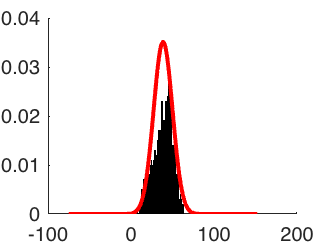

plot(RDstd_0, STD_g, 'r', 'linewidth', 2)

## for the sample max

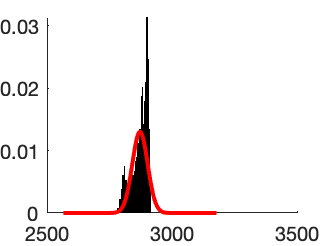

clear f;
figure(9); hold on
bar(xbins_max, distr_max);
max0 =std(RD_max)/10;
Max_0 = (mean(RD_max)-std(RD_max)*10):max0:(mean(RD_max)+std(RD_max)*10);
Maxmu = mean(RD_max);
Maxsig = std(RD_max);
max_g = mypdf(Max_0, Maxmu, Maxsig);
plot(Max_0, max_g, 'r', 'linewidth', 2)

## for sample min

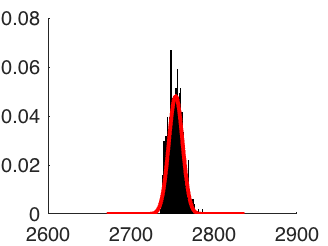

clear f;
figure(10); hold on
bar(xbins_min, distr_min);
max0 =std(RD_min)/10;
Max_0 = (mean(RD_min)-std(RD_min)*10):max0:(mean(RD_min)+std(RD_min)*10);
Maxmu = mean(RD_min);
Maxsig = std(RD_min);
max_g = mypdf(Max_0, Maxmu, Maxsig);
plot(Max_0, max_g, 'r', 'linewidth', 2)

## Problem 8

IDmu = find(RD_mean<=D_mean) 

IDmu =      8    10    11    14    15    16    18    19    22    23    25    27    28    36    37    39    42    43    47    48    49    52    56    57    63    65    66    68    69    70    71    72    74    75    76    77    78    79    80    81    82    86    88    90    91    96    97   104   105   106


perc_mu = length(IDmu)/length(RD_mean) 

perc_mu = 0.5080

perc_mu = perc_mu*100

perc_mu = 50.8000


fprintf( '%f chance of finding a value less than the true mean', perc_mu)

50.800000 chance of finding a value less than the true mean

## Problem 9

tru_max = find(RD_max>(0.99*D_max) & RD_max<(1.01*D_max)) 

tru_max =      4     7     9    11    12    15    20    23    25    26    28    31    32    35    36    37    38    40    46    47    50    51    53    55    58    59    60    61    64    66    68    74    83    84    92    93    94    95    99   100   102   106   107   117   122   124   126   131   132   136


tru_min = find(RD_min>(0.99*D_min) & RD_min<(1.01*D_min)) 

tru_min =      2     3     4     5     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35    36    37    38    39    40    42    43    45    46    47    48    49    50    51    52    53    55    56




%range = tru_max(min(tru_max):max(tru_max)):tru_min(min(tru_min):max(tru_min):2)
perc_max = length(tru_max)/length(RD_max)

perc_max = 0.3530

perc_min  = length(tru_min)/length(RD_min)

perc_min = 0.8600

%Should this be one probabilty

## Problem 10

Elev_Range = find(RD_mean >(D_mean - RDsig) & RD_mean < (D_mean + RDsig))

Elev_Range =      1     2     3     4     8     9    11    12    14    16    17    19    21    23    24    25    26    27    28    29    31    32    33    34    36    37    38    39    41    42    43    44    45    47    48    49    50    51    52    53    55    57    58    64    66    67    68    69    70    71


Prob = RD_mean(Elev_Range)

Prob = 	1.0e+03 *

    2.8013    2.8043    2.8049    2.8036    2.7934    2.8034    2.7887    2.7987    2.7923    2.7871    2.7951    2.7865    2.7979    2.7907    2.8002    2.7934    2.8054    2.7925    2.7865    2.7953    2.8058    2.8002    2.8001    2.7973    2.7938    2.7896    2.7982    2.7917    2.7985    2.7850    2.7861    2.8026    2.8005    2.7935    2.7856    2.7865    2.7959    2.7969    2.7859    2.7994    2.7969    2.7870    2.7985    2.7978    2.7940    2.8071    2.7928    2.7889    2.7855    2.7911


Prob_min = min(Prob) 

Prob_min = 2.7824e+03

Prob_max = max(Prob)

Prob_max = 2.8071e+03

## Problem 11

clear D;
D = load('elevations.txt');

D = D(:); % creates one big long column 
Ix = find(isfinite(D)) %isfinits is putting zeros in a new vector where there are non-finite values 

Ix =      8
     9
    10
    11
    12
    13
    14
    15
    16
    17


                        % and find is finding the values where there are ones and not zeros 

D = D(Ix)

D = 	1.0e+03 *

    2.8803
    2.8788
    2.8774
    2.8759
    2.8738
    2.8657
    2.8576
    2.8496
    2.8436
    2.8402


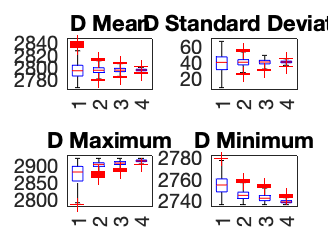


samplesize = [10, 50, 100, 500];
for q= 1:length(samplesize)
    for n = 1:1000
      D2 = randsample(D, samplesize(q), true);
      Dmean(n,q) = mean(D2); % mean of D2
      Dmin(n,q) = min(D2) ;
      Dstd(n,q) = std(D2);
      Dmax(n,q) = max(D2) ;
    end 
end
figure(11)
subplot(2,2,1)
boxplot(Dmean)
title('D Mean')
subplot(2,2,2)
boxplot(Dstd)
title('D Standard Deviation')
subplot(2,2,3)
boxplot(Dmax)
title('D Maximum')
subplot(2,2,4)
boxplot(Dmin)
title('D Minimum')

## Problem 12 Uniform Sampling


% clear D,Ix, D2, x0, D_std, D_mu, D_std, Didx_mu_200; 

D = load('elevations.txt')

D = 	1.0e+03 *

       NaN    2.8961    2.8966    2.8995    2.9029    2.9056    2.9102    2.9023    2.9005    2.9008    2.9062    2.8945    2.8914    2.8889    2.9016    2.8866    2.8931    2.8863    2.8791    2.8789    2.8758    2.8653    2.8658    2.8611    2.8663    2.8469    2.8459    2.8553    2.8408    2.8356    2.8334    2.8417    2.8389    2.8268    2.8237    2.8145    2.8093    2.8118    2.7991    2.8079    2.8030    2.7985    2.7938    2.7964    2.7997    2.7814    2.7821    2.7953    2.7840    2.7835
       NaN    2.8896    2.8996    2.8978    2.9059    2.9122    2.9041    2.9064    2.9037    2.9000    2.9006    2.9006    2.8961    2.9044    2.8878    2.8863    2.8849    2.8908    2.8748    2.8712    2.8762    2.8750    2.8644    2.8654    2.8478    2.8589    2.8501    2.8516    2.8410    2.8418    2.8339    2.8301    2.8281    2.8253    2.8197    2.8144    2.8184    2.8089    2.8004    2.8086    2.8041    2.7955    2.7936    2.7919    2.7827    2.7930    2.7971    2.7881   

nx = 22

nx = 22

nr = 111

nr = 111

nc = 110

nc = 110

Ix=1:nx:nc

Ix =      1    23    45    67    89


Iy = 1:nx:nr

Iy =      1    23    45    67    89   111


% this time we leave D as a matrix (110x111)
%plot the realtive density histogram 
D_idx = zeros(size(D));
%index D with a vector that describes the rows and clolumns we want 
% Ix = find(isfinite(D)) %isfinits is putting zeros in a new vector where there are non-finite values 
                        % and find is finding the values where there are ones and not zeros 

for x = 1:1:22  %This creates the values to be stored in rows 
    for y= 1:1:22 %This stores the y-axis values 
    Iy1 = y:nx:nr;
    Ix1 = x:nx:nc;
    D_idx = D(Ix1, Iy1); %create the array that stores row and column vectors from Ix1 and Iy1
    D_idx = D_idx(:); %this makes D_idx a column 
    Didx_mu_200(x,y) = nanmean(D_idx); 
    Didx_min_200(x,y) = nanmin(D_idx(:));
    Didx_max_200(x,y) = nanmax(D_idx(:));
    Didx_std_200(x,y) = nanstd(D_idx(:));
    end 
end
%For the standard deviation off of mean
Didx_mu_200c = Didx_mu_200(:);  %same process as before when creating normal distribution 
D_muc = mean(Didx_mu_200c);
D_std = std(Didx_mu_200c);
zx =(D_muc-10*D_std):D_std/10:(D_muc+10*D_std)

zx = 	1.0e+03 *

    2.7626    2.7629    2.7632    2.7636    2.7639    2.7642    2.7645    2.7649    2.7652    2.7655    2.7658    2.7661    2.7665    2.7668    2.7671    2.7674    2.7677    2.7681    2.7684    2.7687    2.7690    2.7694    2.7697    2.7700    2.7703    2.7706    2.7710    2.7713    2.7716    2.7719    2.7722    2.7726    2.7729    2.7732    2.7735    2.7739    2.7742    2.7745    2.7748    2.7751    2.7755    2.7758    2.7761    2.7764    2.7767    2.7771    2.7774    2.7777    2.7780    2.7784


gauss_c = mypdf(zx, D_muc, D_std);
%Make Plots
figure(12);
subplot(2,2,1)
histogram(Didx_mu_200c, 30,'Normalization','pdf'); hold on 
plot(zx, gauss_c, 'r')
title('D Mean')

%for maximum 
clear zx, gauss_c, D_std; 

gauss_c =     0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


Didx_max_200c = Didx_max_200(:);
D_mux = mean(Didx_max_200c);
D_std = std(Didx_max_200c);
zx =(D_mux-10*D_std):D_std/10:(D_mux+10*D_std)

zx = 	1.0e+03 *

    2.8040    2.8049    2.8059    2.8068    2.8078    2.8087    2.8096    2.8106    2.8115    2.8124    2.8134    2.8143    2.8153    2.8162    2.8171    2.8181    2.8190    2.8199    2.8209    2.8218    2.8228    2.8237    2.8246    2.8256    2.8265    2.8274    2.8284    2.8293    2.8303    2.8312    2.8321    2.8331    2.8340    2.8349    2.8359    2.8368    2.8377    2.8387    2.8396    2.8406    2.8415    2.8424    2.8434    2.8443    2.8452    2.8462    2.8471    2.8481    2.8490    2.8499


gauss_c = mypdf(zx, D_mux, D_std);

subplot(2,2,2)
histogram(Didx_max_200c, 30,'Normalization','pdf'); hold on 
plot(zx, gauss_c, 'r')
title('D Max')

%for minimum 
clear zx, gauss_c, D_std;

gauss_c =     0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


Didx_min_200c = Didx_min_200(:);
D_mui = mean(Didx_min_200c);
D_std = std(Didx_min_200c);
zx =(D_mui-10*D_std):D_std/10:(D_mui+10*D_std)

zx = 	1.0e+03 *

    2.7005    2.7009    2.7014    2.7019    2.7023    2.7028    2.7032    2.7037    2.7042    2.7046    2.7051    2.7055    2.7060    2.7064    2.7069    2.7074    2.7078    2.7083    2.7087    2.7092    2.7097    2.7101    2.7106    2.7110    2.7115    2.7120    2.7124    2.7129    2.7133    2.7138    2.7142    2.7147    2.7152    2.7156    2.7161    2.7165    2.7170    2.7175    2.7179    2.7184    2.7188    2.7193    2.7198    2.7202    2.7207    2.7211    2.7216    2.7220    2.7225    2.7230


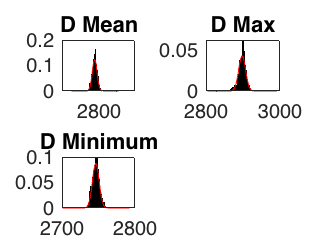

gauss_c = mypdf(zx, D_mui, D_std);
%Make plots
subplot(2,2,3)
histogram(Didx_min_200c, 30,'Normalization','pdf'); hold on 
plot(zx, gauss_c, 'r')
title('D Minimum')

## Problem 13

figure(12)
clear D,D2, x0, D_std, Ix1, Iy1, D_idx, Ix, Iy ; 

D2 = 	1.0e+03 *

    2.8030
    2.7947
    2.7629
    2.7699
    2.8488
    2.8660
    2.7581
    2.7859
    2.7754
    2.7608


x0 = 	1.0e+03 *

   -1.2222   -1.2218   -1.2214   -1.2210   -1.2206   -1.2202   -1.2198   -1.2194   -1.2190   -1.2186   -1.2182   -1.2178   -1.2174   -1.2170   -1.2166   -1.2162   -1.2158   -1.2154   -1.2150   -1.2146   -1.2142   -1.2138   -1.2134   -1.2130   -1.2126   -1.2122   -1.2118   -1.2114   -1.2110   -1.2106   -1.2102   -1.2098   -1.2094   -1.2090   -1.2086   -1.2082   -1.2078   -1.2074   -1.2070   -1.2066   -1.2062   -1.2058   -1.2054   -1.2050   -1.2046   -1.2042   -1.2038   -1.2034   -1.2030   -1.2026


D_std = 4.5881

Ix1 =     22    44    66    88   110


Iy1 =     22    44    66    88   110


D_idx = 	1.0e+03 *

    2.8266
    2.7744
    2.7858
    2.8532
    2.9069
    2.7775
    2.7696
    2.7652
    2.8345
    2.8992


Ix =      1    23    45    67    89



D = load('elevations.txt')

D = 	1.0e+03 *

       NaN    2.8961    2.8966    2.8995    2.9029    2.9056    2.9102    2.9023    2.9005    2.9008    2.9062    2.8945    2.8914    2.8889    2.9016    2.8866    2.8931    2.8863    2.8791    2.8789    2.8758    2.8653    2.8658    2.8611    2.8663    2.8469    2.8459    2.8553    2.8408    2.8356    2.8334    2.8417    2.8389    2.8268    2.8237    2.8145    2.8093    2.8118    2.7991    2.8079    2.8030    2.7985    2.7938    2.7964    2.7997    2.7814    2.7821    2.7953    2.7840    2.7835
       NaN    2.8896    2.8996    2.8978    2.9059    2.9122    2.9041    2.9064    2.9037    2.9000    2.9006    2.9006    2.8961    2.9044    2.8878    2.8863    2.8849    2.8908    2.8748    2.8712    2.8762    2.8750    2.8644    2.8654    2.8478    2.8589    2.8501    2.8516    2.8410    2.8418    2.8339    2.8301    2.8281    2.8253    2.8197    2.8144    2.8184    2.8089    2.8004    2.8086    2.8041    2.7955    2.7936    2.7919    2.7827    2.7930    2.7971    2.7881   

nx = 3

nx = 3

nr = 111

nr = 111

nc = 110

nc = 110

Ix=1:nx:nc

Ix =      1     4     7    10    13    16    19    22    25    28    31    34    37    40    43    46    49    52    55    58    61    64    67    70    73    76    79    82    85    88    91    94    97   100   103   106   109


Iy = 1:nx:nr

Iy =      1     4     7    10    13    16    19    22    25    28    31    34    37    40    43    46    49    52    55    58    61    64    67    70    73    76    79    82    85    88    91    94    97   100   103   106   109


% this time we leave D as a matrix (110x111)
%plot the realtive density histogram 
%index D with a vector that describes the rows and clolumns we want 
 %isfinits is putting zeros in a new vector where there are non-finite values 
                        % and find is finding the values where there are ones and not zeros 

for x = 1:1:3
    for y= 1:1:3
    Iy1 = y:nx:nr;
    Ix1 = x:nx:nc;
    D_idx = D(Ix1, Iy1);
%     D_idx = D_idx(isfinite(D_idx));
%     D_idx = D_idx(:);
    Didx_mu_30(x,y) = nanmean(D_idx(:));
    Didx_min_30(x,y) = nanmin(D_idx(:));
    Didx_max_30(x,y) = nanmax(D_idx(:));
    Didx_std_30(x,y) = nanstd(D_idx(:));
    end 
end
%For the standard deviation off of mean
clear D_muc, D_std, D_mux, D_mui, zx, gauss_c;

D_std = 4.5881

D_mux = 2.8977e+03

D_mui = 2.7464e+03

zx = 	1.0e+03 *

    2.7005    2.7009    2.7014    2.7019    2.7023    2.7028    2.7032    2.7037    2.7042    2.7046    2.7051    2.7055    2.7060    2.7064    2.7069    2.7074    2.7078    2.7083    2.7087    2.7092    2.7097    2.7101    2.7106    2.7110    2.7115    2.7120    2.7124    2.7129    2.7133    2.7138    2.7142    2.7147    2.7152    2.7156    2.7161    2.7165    2.7170    2.7175    2.7179    2.7184    2.7188    2.7193    2.7198    2.7202    2.7207    2.7211    2.7216    2.7220    2.7225    2.7230


Didx_mu_30q = Didx_mu_30(:);
D_muc = mean(Didx_mu_30q);
D_std = std(Didx_mu_30q);
zx =(D_muc-10*D_std):D_std/10:(D_muc+10*D_std)

zx = 	1.0e+03 *

    2.7887    2.7887    2.7888    2.7888    2.7889    2.7890    2.7890    2.7891    2.7891    2.7892    2.7893    2.7893    2.7894    2.7895    2.7895    2.7896    2.7896    2.7897    2.7898    2.7898    2.7899    2.7899    2.7900    2.7901    2.7901    2.7902    2.7902    2.7903    2.7904    2.7904    2.7905    2.7906    2.7906    2.7907    2.7907    2.7908    2.7909    2.7909    2.7910    2.7910    2.7911    2.7912    2.7912    2.7913    2.7913    2.7914    2.7915    2.7915    2.7916    2.7916


gauss_c = mypdf(zx, D_muc, D_std);
%Make Plots
figure(13);
subplot(2,2,1)
histogram(Didx_mu_30q, 30,'Normalization','pdf'); hold on 
plot(zx, gauss_c, 'r')
title('D Mean')

%for maximum 
clear zx, gauss_c, D_std; 

gauss_c =     0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


Didx_max_30q = Didx_max_30(:);
D_mux = mean(Didx_max_30q);
D_std = std(Didx_max_30q);
zx =(D_mux-10*D_std):D_std/10:(D_mux+10*D_std)

zx = 	1.0e+03 *

    2.8865    2.8868    2.8871    2.8874    2.8877    2.8880    2.8883    2.8885    2.8888    2.8891    2.8894    2.8897    2.8900    2.8903    2.8905    2.8908    2.8911    2.8914    2.8917    2.8920    2.8922    2.8925    2.8928    2.8931    2.8934    2.8937    2.8940    2.8942    2.8945    2.8948    2.8951    2.8954    2.8957    2.8960    2.8962    2.8965    2.8968    2.8971    2.8974    2.8977    2.8980    2.8982    2.8985    2.8988    2.8991    2.8994    2.8997    2.9000    2.9002    2.9005


gauss_c = mypdf(zx, D_mux, D_std);

subplot(2,2,2)
histogram(Didx_max_30q, 30,'Normalization','pdf'); hold on 
plot(zx, gauss_c, 'r')
title('D Max')

%for minimum 
clear zx, gauss_c, D_std;

gauss_c =     0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


Didx_min_30q = Didx_min_30(:);
D_mui = mean(Didx_min_30q);
D_std = std(Didx_min_30q);
zx =(D_mui-10*D_std):D_std/10:(D_mui+10*D_std)

zx = 	1.0e+03 *

    2.7296    2.7297    2.7298    2.7299    2.7299    2.7300    2.7301    2.7302    2.7302    2.7303    2.7304    2.7305    2.7305    2.7306    2.7307    2.7308    2.7308    2.7309    2.7310    2.7311    2.7311    2.7312    2.7313    2.7314    2.7314    2.7315    2.7316    2.7317    2.7317    2.7318    2.7319    2.7320    2.7320    2.7321    2.7322    2.7323    2.7323    2.7324    2.7325    2.7326    2.7326    2.7327    2.7328    2.7329    2.7329    2.7330    2.7331    2.7332    2.7332    2.7333


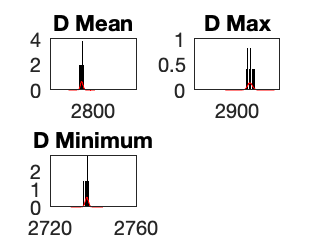

gauss_c = mypdf(zx, D_mui, D_std);
%Make plots
subplot(2,2,3)
histogram(Didx_min_30q, 30,'Normalization','pdf'); hold on 
plot(zx, gauss_c, 'r')
title('D Minimum')

## Problem 14

clear D,Ix, Ix1, Iy1, D_idx, Dstd, Dmax, Dmin, Dmean;

Ix =      1     4     7    10    13    16    19    22    25    28    31    34    37    40    43    46    49    52    55    58    61    64    67    70    73    76    79    82    85    88    91    94    97   100   103   106   109


Ix1 =      3     6     9    12    15    18    21    24    27    30    33    36    39    42    45    48    51    54    57    60    63    66    69    72    75    78    81    84    87    90    93    96    99   102   105   108


Iy1 =      3     6     9    12    15    18    21    24    27    30    33    36    39    42    45    48    51    54    57    60    63    66    69    72    75    78    81    84    87    90    93    96    99   102   105   108   111


D_idx = 	1.0e+03 *

    2.9041    2.9027    2.9099    2.8985    2.8915    2.8773    2.8795    2.8673    2.8459    2.8518    2.8365    2.8183    2.8007    2.8040    2.8010    2.7882    2.7886    2.7846    2.7760    2.7725    2.7697    2.7790    2.7792    2.7899    2.8028    2.7926    2.8010    2.7923    2.7946    2.7926    2.8004    2.7901    2.7892    2.7967    2.8009    2.7975       NaN
    2.8932    2.8953    2.9087    2.8997    2.8910    2.8974    2.8665    2.8730    2.8476    2.8545    2.8376    2.8184    2.8042    2.8049    2.7821    2.7892    2.7871    2.7783    2.7826    2.7764    2.7832    2.7703    2.7942    2.7847    2.7921    2.7995    2.8022    2.8061    2.7928    2.7876    2.7899    2.7894    2.8062    2.7935    2.7921    2.8068       NaN
    2.8735    2.8961    2.8913    2.8952    2.8948    2.8863    2.8754    2.8679    2.8654    2.8413    2.8271    2.8229    2.8049    2.7936    2.7907    2.7768    2.7885    2.7833    2.7738    2.7825    2.7741    2.7713    2.7911    2.78

Dstd =    33.5266   43.7335   41.6958   40.3003
   50.3870   37.2108   39.8736   41.4775
   35.1664   36.5607   38.0851   39.9353
   39.2778   51.1845   39.3311   39.7442
   48.3159   41.1038   42.1791   39.2359
   36.4414   33.3949   37.4042   38.7412
   43.4336   39.9271   39.3422   40.2807
   37.0121   42.6038   40.0143   37.9971
   47.8008   46.0650   40.5435   41.6068
   28.0713   37.7360   37.2027   39.3399


Dmax = 	1.0e+03 *

    2.8858    2.8984    2.9050    2.9156
    2.8951    2.8981    2.8991    2.9156
    2.8740    2.9005    2.9084    2.9095
    2.8858    2.9069    2.9187    2.9097
    2.9011    2.9009    2.9075    2.9156
    2.8562    2.8894    2.9045    2.9014
    2.9112    2.8857    2.9060    2.9187
    2.9010    2.9079    2.9072    2.9153
    2.8944    2.9121    2.9048    2.9122
    2.8520    2.8879    2.8957    2.9112


Dmin = 	1.0e+03 *

    2.7723    2.7421    2.7437    2.7380
    2.7599    2.7472    2.7428    2.7373
    2.7596    2.7430    2.7426    2.7405
    2.7433    2.7455    2.7392    2.7398
    2.7577    2.7501    2.7466    2.7405
    2.7476    2.7426    2.7408    2.7389
    2.7646    2.7389    2.7469    2.7392
    2.7765    2.7446    2.7463    2.7394
    2.7550    2.7438    2.7375    2.7392
    2.7479    2.7435    2.7422    2.7373


D = load('elevations.txt')

D = 	1.0e+03 *

       NaN    2.8961    2.8966    2.8995    2.9029    2.9056    2.9102    2.9023    2.9005    2.9008    2.9062    2.8945    2.8914    2.8889    2.9016    2.8866    2.8931    2.8863    2.8791    2.8789    2.8758    2.8653    2.8658    2.8611    2.8663    2.8469    2.8459    2.8553    2.8408    2.8356    2.8334    2.8417    2.8389    2.8268    2.8237    2.8145    2.8093    2.8118    2.7991    2.8079    2.8030    2.7985    2.7938    2.7964    2.7997    2.7814    2.7821    2.7953    2.7840    2.7835
       NaN    2.8896    2.8996    2.8978    2.9059    2.9122    2.9041    2.9064    2.9037    2.9000    2.9006    2.9006    2.8961    2.9044    2.8878    2.8863    2.8849    2.8908    2.8748    2.8712    2.8762    2.8750    2.8644    2.8654    2.8478    2.8589    2.8501    2.8516    2.8410    2.8418    2.8339    2.8301    2.8281    2.8253    2.8197    2.8144    2.8184    2.8089    2.8004    2.8086    2.8041    2.7955    2.7936    2.7919    2.7827    2.7930    2.7971    2.7881   


 %isfinits is putting zeros in a new vector where there are non-finite values 
                        % and find is finding the values where there are ones and not zeros 

nr = 111

nr = 111

nc = 110

nc = 110

samplesize = [50, 100, 200, 400,500]

samplesize =     50   100   200   400   500


for q= 1:length(samplesize)
    nx = round(samplesize(q)/9);

    for x = 1:1:nx  %same for loop as before except now it will vary with sample size 
        for y = 1:1:nx
        Iy1 = y:nx:nr;
        Ix1 = x:nx:nc;
        D_idx = D(Ix1, Iy1);      
        Didx_mu(x,y) = nanmean(D_idx(:));
        Didx_min(x,y) = nanmin(D_idx(:));
        Didx_max(x,y) = nanmax(D_idx(:));
        Didx_std(x,y) = nanstd(D_idx(:));
        end
     
    end 
    x_mu(q) = nanmean(Didx_mu(:));  %store the mean of the mean values for each sample size 'q'
    x_std(q) = nanstd(Didx_mu(:)) %store the standard deviation of mean values for each sample size 'q'
    len(q) = length(Didx_mu) % number of samples for each sample size 'q'
    x_mux(q) = nanmean(Didx_max(:));
    x_mui(q) = nanmean(Didx_min(:));
    x_stx(q) = nanstd(Didx_max(:));
    x_sti(q) = nanstd(Didx_min(:));
end

x_std = 1.0383

len = 6

x_std =     1.0383    1.5468


len =      6    11


x_std =     1.0383    1.5468    3.2154


len = 1×3
     6    11    22


x_std = 1×4
    1.0383    1.5468    3.2154   10.6589


len = 1×4
     6    11    22    44


x_std = 1×5
    1.0383    1.5468    3.2154   10.6589   11.2325


len = 1×5
     6    11    22    44    56


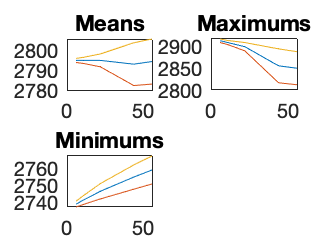


figure(14)
subplot(2,2,1)
plot(len, x_mu); hold on %plot length versus mean
plot(len, x_mu-x_std); hold on %plot length versus mean minus the std
plot(len, x_mu+x_std);  %plot length versus mean plus std
title('Means')
subplot(2,2,2)
plot(len, x_mux); hold on %plot length versus mean
plot(len, x_mux-x_stx); hold on %plot length versus mean minus the std
plot(len, x_mux+x_stx);
title( 'Maximums')
subplot(2,2,3)
plot(len, x_mui); hold on %plot length versus mean
plot(len, x_mui-x_sti); hold on %plot length versus mean minus the std
plot(len, x_mui+x_sti);
title( 'Minimums')

## GAUSSIAN FUNCTION

function f =mypdf(z,mu,sig)

A = 1/(sig*sqrt(2*pi));
B = (z-mu).^2;
C = 2*sig.^2;
f = A*exp(-B./C);
end